This script compare  the raw data (after BIDS conversion, separated into runs, identified bad channels), the results of common-averaged re-reference (CAR), and independent component analysis re-reference (ICA).

In CAR, the average was computed using good channels only, and the average re-reference was applied to all channels.

In ICA, I removed two components with the greatest broadness (component 1, 120; see Sorted_Comp_LOADINGS.png ).

clear; close all;

tbUse tactileTemporalECoG

projectDir        = '/Volumes/server/Projects/BAIR/Data/BIDS/tactile';
subject           = 'ny726';
tasks             = 'temporalpattern';
sessions          = 'nyuecog01';
runnums           = [];
figureDir         = fullfile(projectDir, 'derivatives', 'compare_ICA_CAR');

%% Load data, make epochs

% Specify data
[session, tasks, runnums] = bidsSpecifyData(projectDir, subject, sessions, tasks, []);

% Get the raw data from BIDS folder
% Data: channel x time series across 5 runs
[data, channels, events, srate] = bidsEcogGetPreprocData(projectDir, subject, sessions, tasks);

[bidsEcogGetPreprocData] Concatenating runs for session nyuecog01, task temporalpattern...
[bidsEcogReadFiles] Reading from /Volumes/server/Projects/BAIR/Data/BIDS/tactile/sub-ny726/ses-nyuecog01/ieeg
[bidsEcogReadFiles] Reading sub-ny726_ses-nyuecog01_task-temporalpattern*_run-01*
...found matching BIDS sidecar '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_acq-clinical_run-01_ieeg.json'
reading '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_acq-clinical_run-01_ieeg.json'
found matching BIDS sidecar '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_acq-clinical_run-01_channels.tsv'
reading '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_acq-clinical_run-01_channels.tsv'
found matching BIDS 


% Epoch by onset: time series x trial x channel
onset_epoch_t = [-0.5, 1.8];  % stimulus epoch window
[epochs, t] = ecog_makeEpochs(data, events.onset, onset_epoch_t, channels.sampling_frequency(1));

%% Load demeaned CAR data

CAR_path = fullfile(projectDir, 'derivatives', 'demean_CAR');
[CAR_data, CAR_channels, CAR_events, CAR_srate] = bidsEcogGetPreprocData(CAR_path, subject, sessions, tasks);

[bidsEcogGetPreprocData] Concatenating runs for session nyuecog01, task temporalpattern...
[bidsEcogReadFiles] Reading from /Volumes/server/Projects/BAIR/Data/BIDS/tactile/derivatives/demean_CAR/sub-ny726/ses-nyuecog01/ieeg
[bidsEcogReadFiles] Reading sub-ny726_ses-nyuecog01_task-temporalpattern*_run-01*
...found matching BIDS sidecar '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/derivatives/demean_CAR/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_run-01_desc-reref_ieeg.json'
reading '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/derivatives/demean_CAR/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_run-01_desc-reref_ieeg.json'
found matching BIDS sidecar '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/derivatives/demean_CAR/sub-ny726/ses-nyuecog01/ieeg/sub-ny726_ses-nyuecog01_task-temporalpattern_run-01_desc-reref_channels.tsv'
reading '/Volumes/server/Projects/BAIR/Data/BIDS/tactile/derivatives/demean_CAR/sub-ny726/ses-nyuec


onset_epoch_t = [-0.5, 1.8];  % stimulus epoch window
[CAR_epochs, CAR_t] = ecog_makeEpochs(CAR_data, CAR_events.onset, onset_epoch_t, CAR_channels.sampling_frequency(1));

% Exclude missing electrode positions for ICA
exclude_chans = {'W14', 'W15', 'H18', 'P10', 'R8', 'S15'}; 
chan_idx = ~ismember(CAR_channels.name, exclude_chans);
CAR_epochs = CAR_epochs(:,:,chan_idx);
CAR_channels = CAR_channels(chan_idx,:);
CAR_data = CAR_data(chan_idx,:);

%% Load ICA data

ICA_path = fullfile(projectDir, 'derivatives', 'ICA_reref');
D = load(fullfile(ICA_path, 'ieeg_reref.mat'));

ICA_data = D.ieeg_reref.trial{1};
ICA_fs = D.ieeg_reref.fsample;
[ICA_epochs, ICA_t] = ecog_makeEpochs(ICA_data, events.onset, onset_epoch_t, ICA_fs);

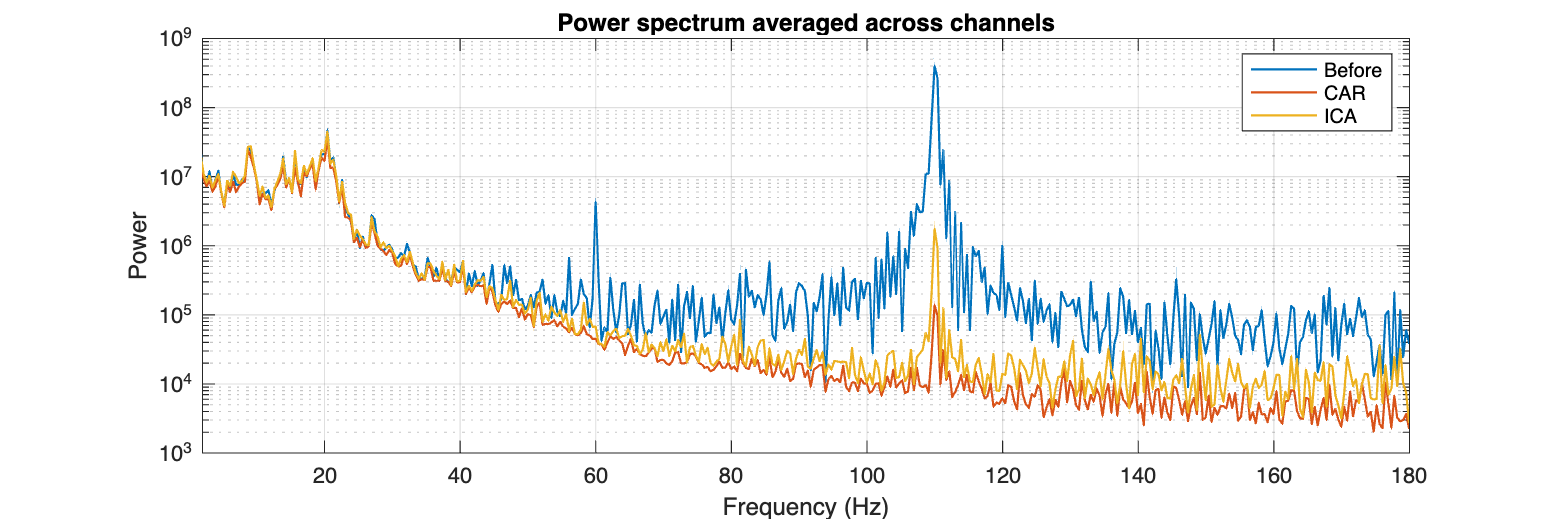


%% 1. Plot power spectrum comparison for a random long one-pulse trial

% Select 1 long, one-pulse trial
all_long_trial_idx = find(contains(events.trial_name, 'ONE-PULSE-6'));
trial_idx = all_long_trial_idx(randi(numel(all_long_trial_idx),1));

% FFT for each version
Fs = srate; % sampling frequency
L = length(t); % length of signal
f = Fs*(0:(L/2))/L; % frequency vector

% FFT for each channel, then averaged across channels
raw_fft = mean(abs(fft(squeeze(epochs(:,trial_idx,:)))).^2,2);
car_fft = mean(abs(fft(squeeze(CAR_epochs(:,trial_idx,:)))).^2,2);
ica_fft = mean(abs(fft(squeeze(ICA_epochs(:,trial_idx,:)))).^2,2);

% Up to Nyquist frequency
raw_fft = raw_fft(1:floor(L/2)+1,:);
car_fft = car_fft(1:floor(L/2)+1,:);
ica_fft = ica_fft(1:floor(L/2)+1,:);

figure;
set(gcf, 'Position', [0 0 1200 400]);
semilogy(f, raw_fft, 'LineWidth', 1,'DisplayName','Before'); hold on
semilogy(f, car_fft, 'LineWidth', 1,'DisplayName','CAR');
semilogy(f, ica_fft, 'LineWidth', 1,'DisplayName','ICA');
title('Power spectrum averaged across channels')
xlabel('Frequency (Hz)');
ylabel('Power');
grid on;
xlim([2 180]); 
legend

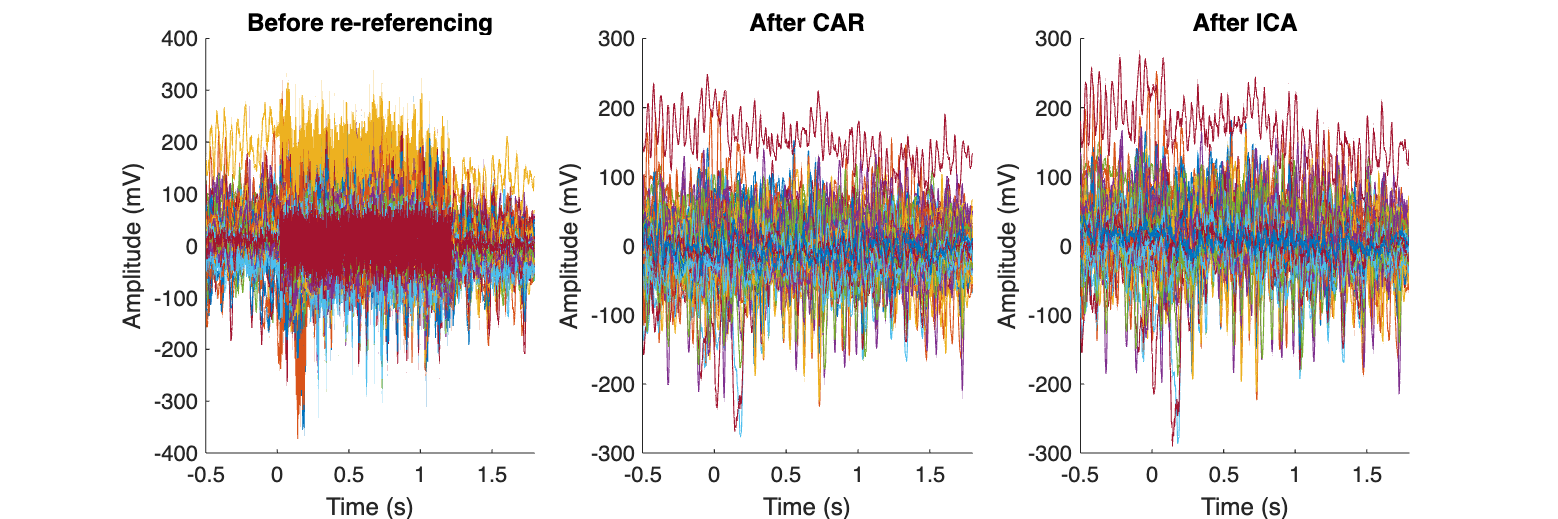


%% 2. Plot time series across channels for a random long one-pulse trial

figure; 
set(gcf, 'Position', [0 0 2400 800]);
subplot(1,3,1);hold on
title('Before re-referencing');
plot(t, squeeze(epochs(:,trial_idx,:)));
xlim([min(t), max(t)])
xlabel('Time (s)')
ylabel('Amplitude (mV)')

subplot(1,3,2);hold on
title('After CAR');
plot(t, squeeze(CAR_epochs(:,trial_idx,:)));
xlim([min(t), max(t)])
ylim([-400 300])
xlabel('Time (s)')
ylabel('Amplitude (mV)')

subplot(1,3,3);hold on
title('After ICA');
plot(t, squeeze(ICA_epochs(:,trial_idx,:)));
xlim([min(t), max(t)])
ylim([-400 300])
xlabel('Time (s)')
ylabel('Amplitude (mV)')

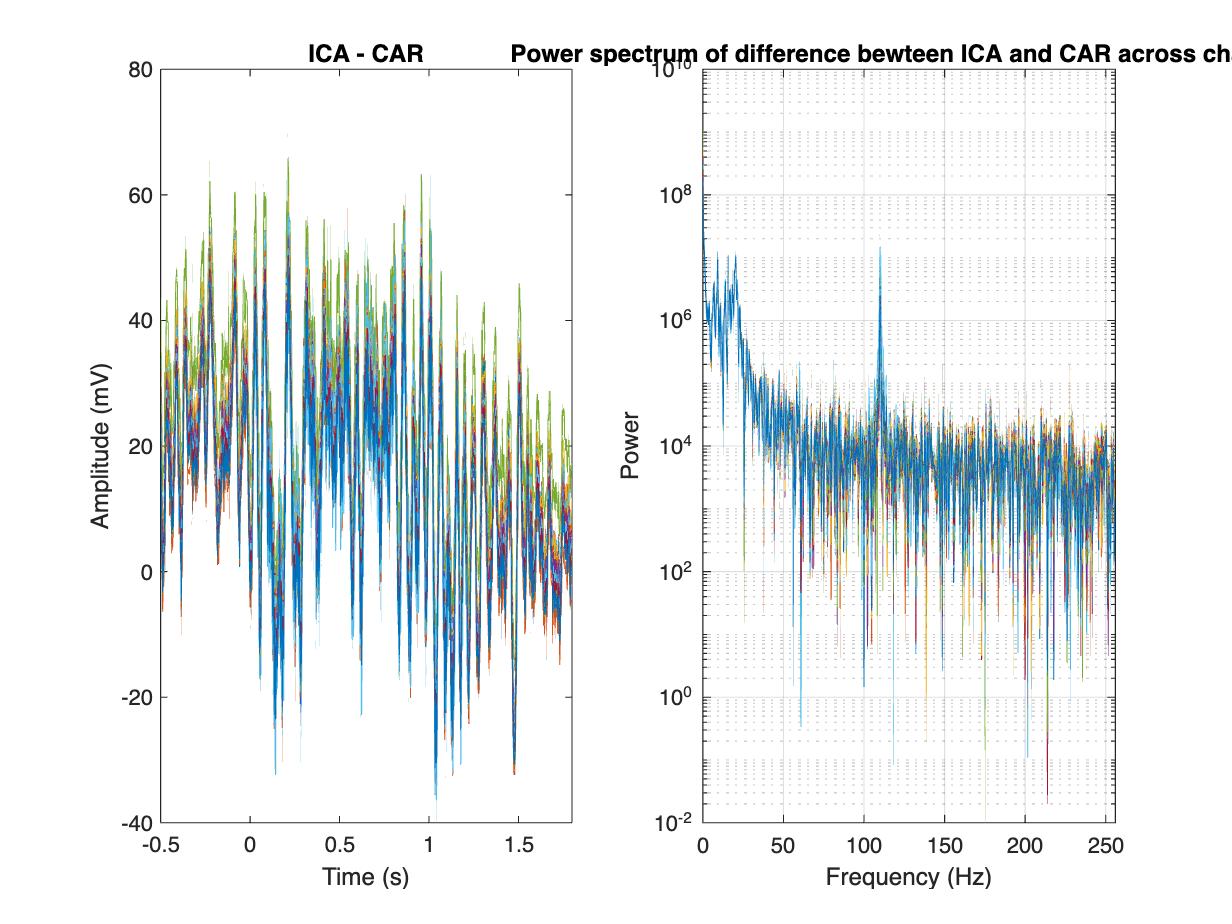


%% 3. Plot the difference between ICA and CAR for a random long one-pulse trial across channels

diff = squeeze(ICA_epochs(:,trial_idx,:) - CAR_epochs(:,trial_idx,:));

figure; hold on
subplot(121)
plot(t, diff);
xlim([min(t), max(t)])
xlabel('Time (s)')
ylabel('Amplitude (mV)')
title('ICA - CAR');

subplot(122);
diff_fft = abs(fft(diff)).^2;
diff_fft = diff_fft(1:floor(L/2)+1,:);
semilogy(f, diff_fft); hold on
xlim([min(f),max(f)])
grid on
title('Power spectrum of difference bewteen ICA and CAR across channels')
xlabel('Frequency (Hz)');
ylabel('Power');

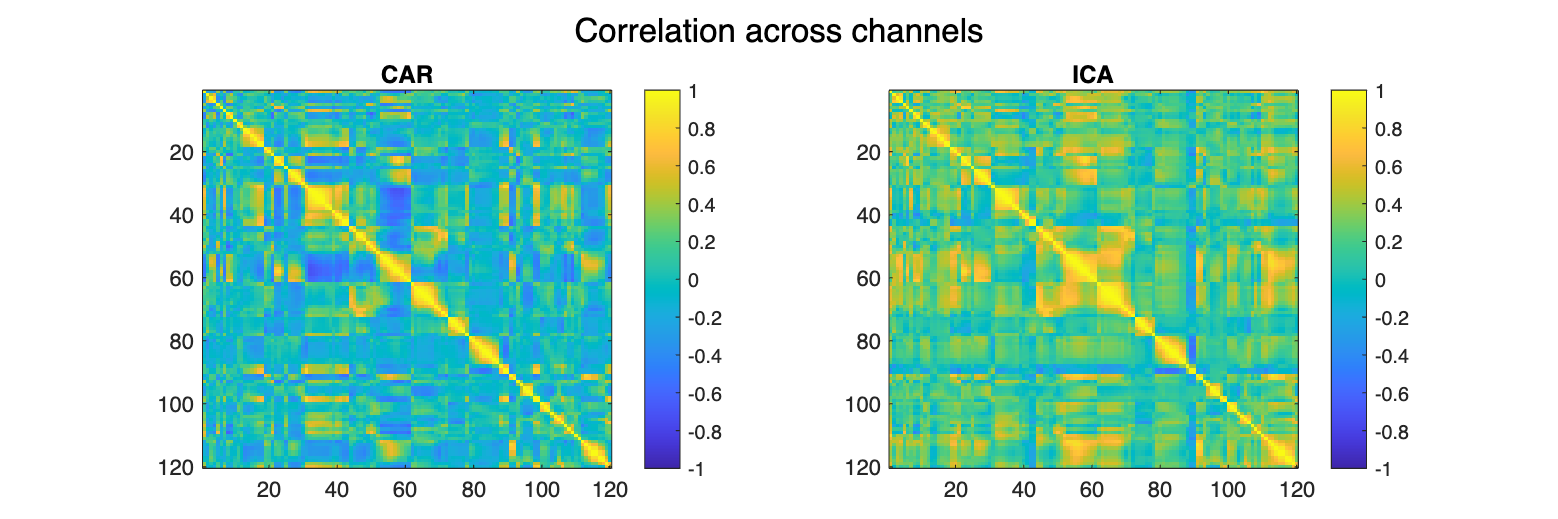



%% 4. Plot correlation across all channels for CAR and ICA

ICA_trial = squeeze(ICA_epochs(:,trial_idx,:));
R_ICA = corr(ICA_trial);

CAR_trial = squeeze(CAR_epochs(:,trial_idx,:));
R_CAR = corr(CAR_trial);

figure; 
set(gcf,'Position',[0,0,1200,400])
sgtitle('Correlation across channels')

subplot(121)
imagesc(R_CAR,[-1, 1])
colorbar
title('CAR')

subplot(122)
imagesc(R_ICA,[-1, 1])
colorbar
title('ICA')

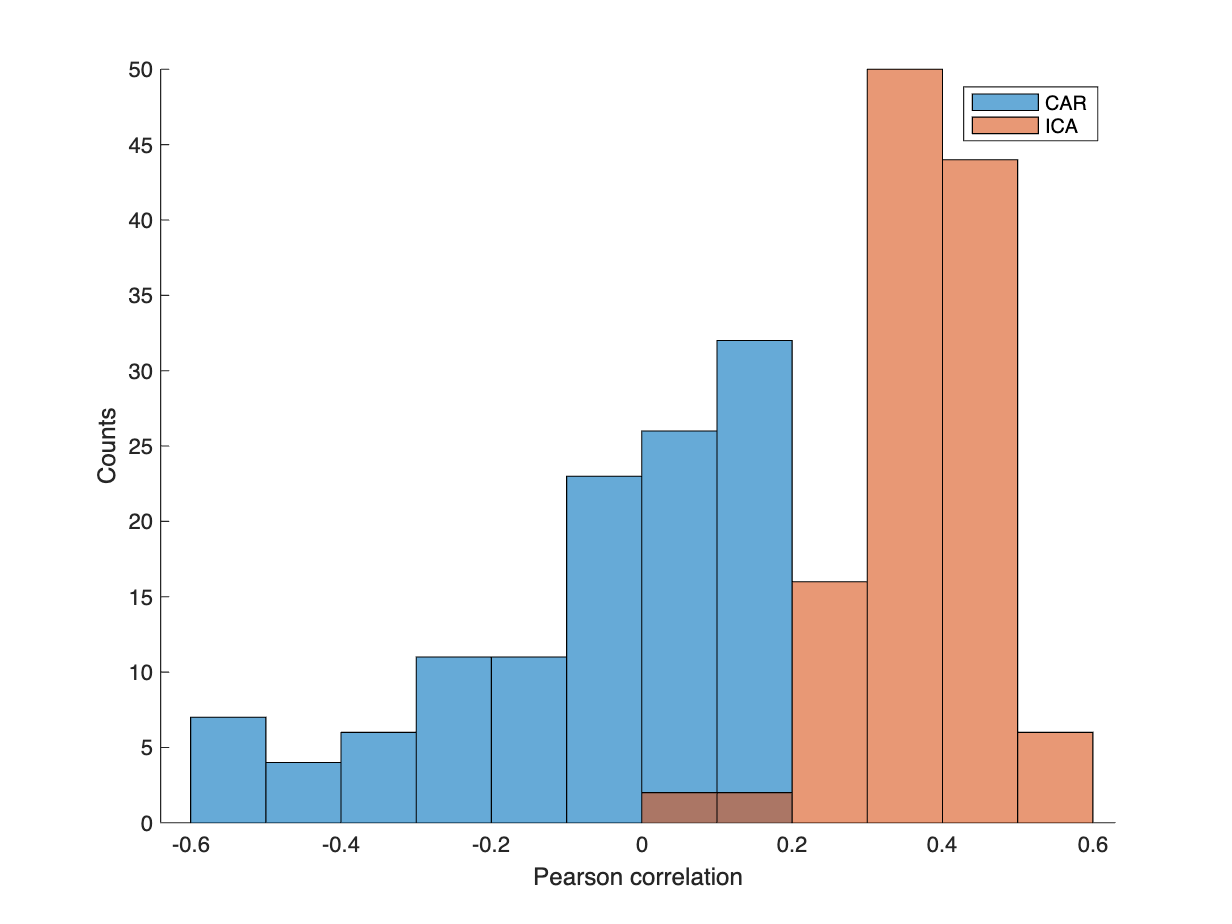


%% 5. Compute correlation between the average and re-referenced data

good_channels = find(contains(channels.status, 'good'));
gmean = mean(data(good_channels,:),1);
for cc = 1:size(CAR_data,1)
    CAR_corr(cc) = corr(gmean(:), CAR_data(cc,:)');
    ICA_corr(cc) = corr(gmean(:), ICA_data(cc,:)');
end

figure; hold on
histogram(CAR_corr,'BinWidth',0.1,'DisplayName','CAR')
histogram(ICA_corr,'BinWidth',0.1, 'DisplayName','ICA')
legend
xlabel('Pearson correlation')
ylabel('Counts')